# Merge estimated masks

close all; clearvars; clc;

### Setup varaibles

#### Conditions

train_on = 1;
visualize = 1;
save_results = 0;

#### Variables

orig_height = 3648;
orig_width = 5472;
merg_img = zeros(orig_height, orig_width, 3);

num_dx = 6;
num_dy = 4;
img_size = size(merg_img);

dx = 912;
dy = 912;

row = 1;
col = 1;

img_save = [];
num_per_img = 1;
merge_num = 1;

num_vis = 1;

if train_on == 1
    total_img = 44;
elseif train_on == 2
    total_img = 43;
end

### Script

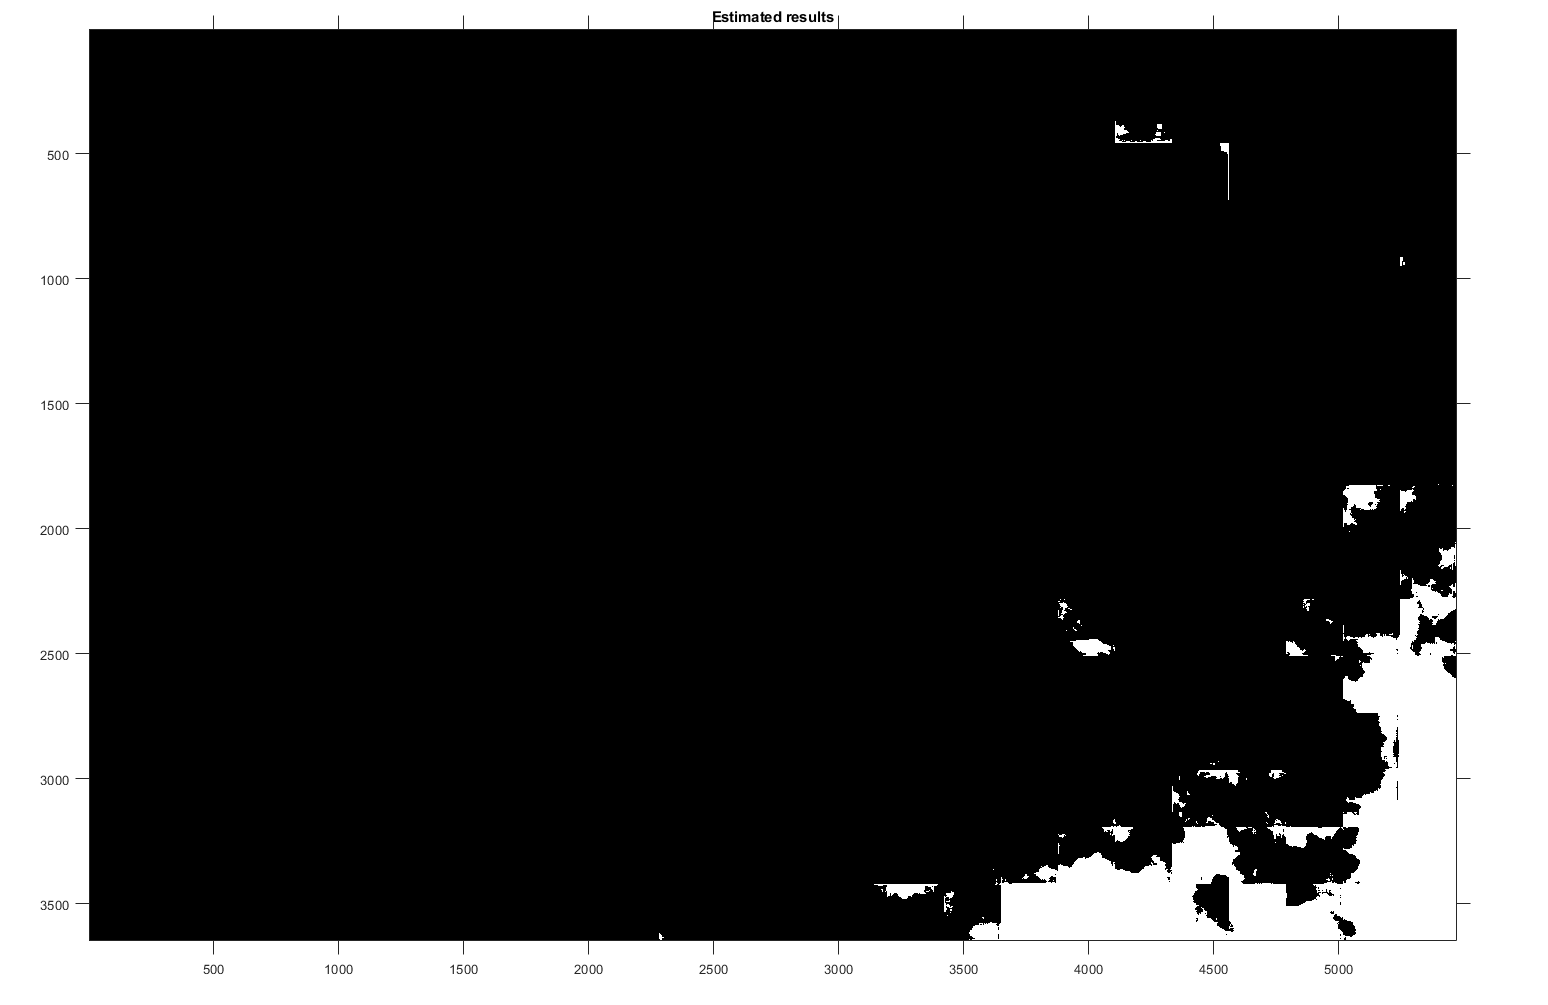

for img_num = 29*24+1:29*24+1+23
    path_esimated_results = "C:/Users/windows/Desktop/Research/3. Code/6. UnetFire/Results/0. Trained model/comparative_studies/img_results/0_patch_level_1_predictions/6";
    cd(path_esimated_results)
    
    img_name = sprintf("predict%g.png", img_num);
    img = imread(img_name);
    img = uint8(img);
    
    try 
        if num_per_img <= num_dx * num_dy
            img_save = [img_save; img];
            num_per_img = num_per_img +1;
        else
            img_save = [];
            num_per_img = 1;
            num_vis = 1;
            img_name = sprintf("predict%g.png", img_num);
            img = imread(img_name);
            img = uint8(img);
            disp('Burned');
            img_save = [img_save; img];
            num_per_img = num_per_img +1;
        end
    catch
        disp(img_num)
        disp('No burned');
    end
    
    if num_vis == 24
        if visualize == 1
            figure('Position',[3000 100 3648 5472]);
        end
        k = 1;
        row_run = 1;
        for row = 1:dx:img_size(2)
            for col = 1:dy:img_size(1)
               
                merge_img(col:col+dy-1,row:row+dx-1,:) = img_save(row_run:dx*k,:,:);
                k = k+1;
                row_run = row_run + dx;
                
                % VISUALIZE
                if visualize == 1
                    imshow(uint8(merge_img))
                    drawnow
                end
                
            end
        end
        axis on
        title('Estimated results')
        % SAVE MERGED ESTIMATED RESULTS
        path_save_merge = "C:/Users/windows/Desktop/Research/3. Code/6. UnetFire/Results/0. Trained model/comparative_studies/img_results/1_merge/proposed_method";
        if save_results == 1
            cd(path_save_merge);
            file_name = sprintf('merge%g.png',merge_num);
            merge_num = merge_num +1;
            imwrite(uint8(merge_img), file_name)
        end
        
    end
    num_vis = num_vis +1;
end

# Composite of two images - orignal and estimated 

path_orig = "C:/Users/windows/Desktop/Research/3. Code/6. UnetFire/ImgLabel/official_data_10.6/location_2_orig_data";
path_estimated_results = path_save_merge;

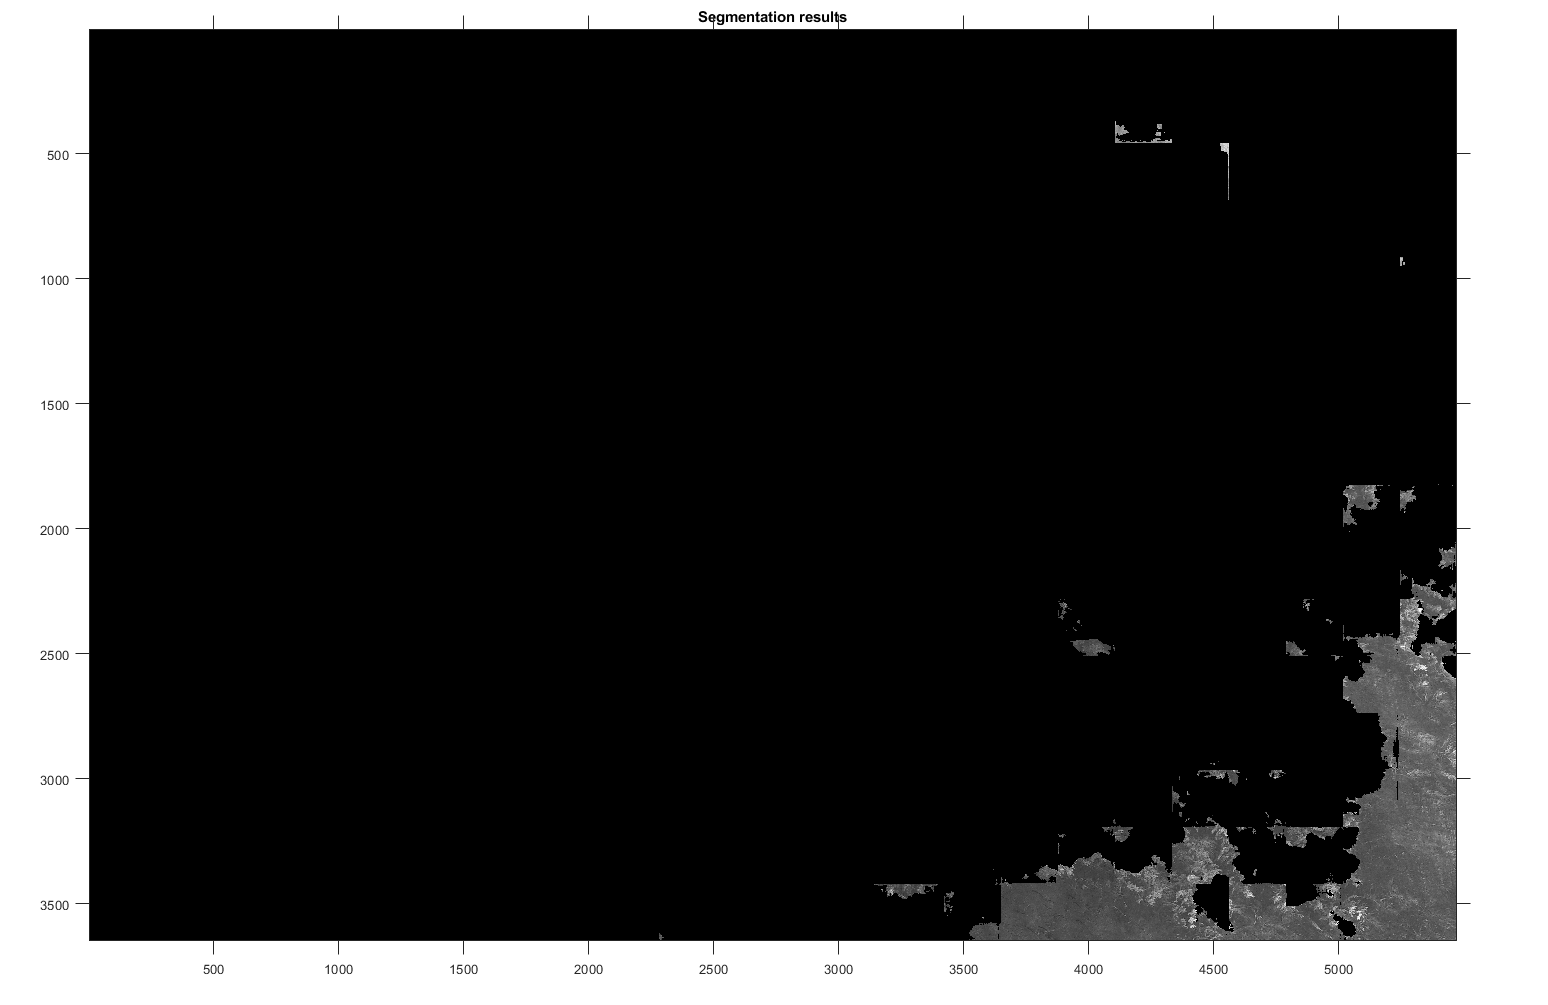

%%
for img_num = 30
    % Load orig data
    cd(path_orig)
    if train_on == 1 
        orig_name = sprintf('orig2 (%g).jpg',img_num);
    elseif train_on == 2
        orig_name = sprintf('orig1 (%g).jpg',img_num);
    end

    orig_img = imread(orig_name);
    
    % Load estimated mask data
    cd(path_estimated_results)
    estimated_name = sprintf('merge%g.png',img_num);

    estimated_result = imread(estimated_name);
    estimated_result = estimated_result/255;
    
    % Merge RGB
    merge_RGB_img = estimated_result.*orig_img;
    
    % Overlay image
%     fuse_img = imfuse(merge_RGB_img, orig_img,'falsecolor','Scaling','joint',[1 2 0]);
    overlay_img = imfuse(merge_RGB_img,orig_img,'falsecolor','Scaling','joint','ColorChannels',[1 2 0]);
    if visualize == 1
        imshow(overlay_img(:,:,1))
    end
    axis on
    title("Segmentation results")
    % Save overlay images
    if save_results == 1
        path_save_overlay = "...";
        cd(path_save_overlay);
        file_name = sprintf('overlay%g.png',img_num);
        imwrite(uint8(overlay_img), file_name)
    end
end

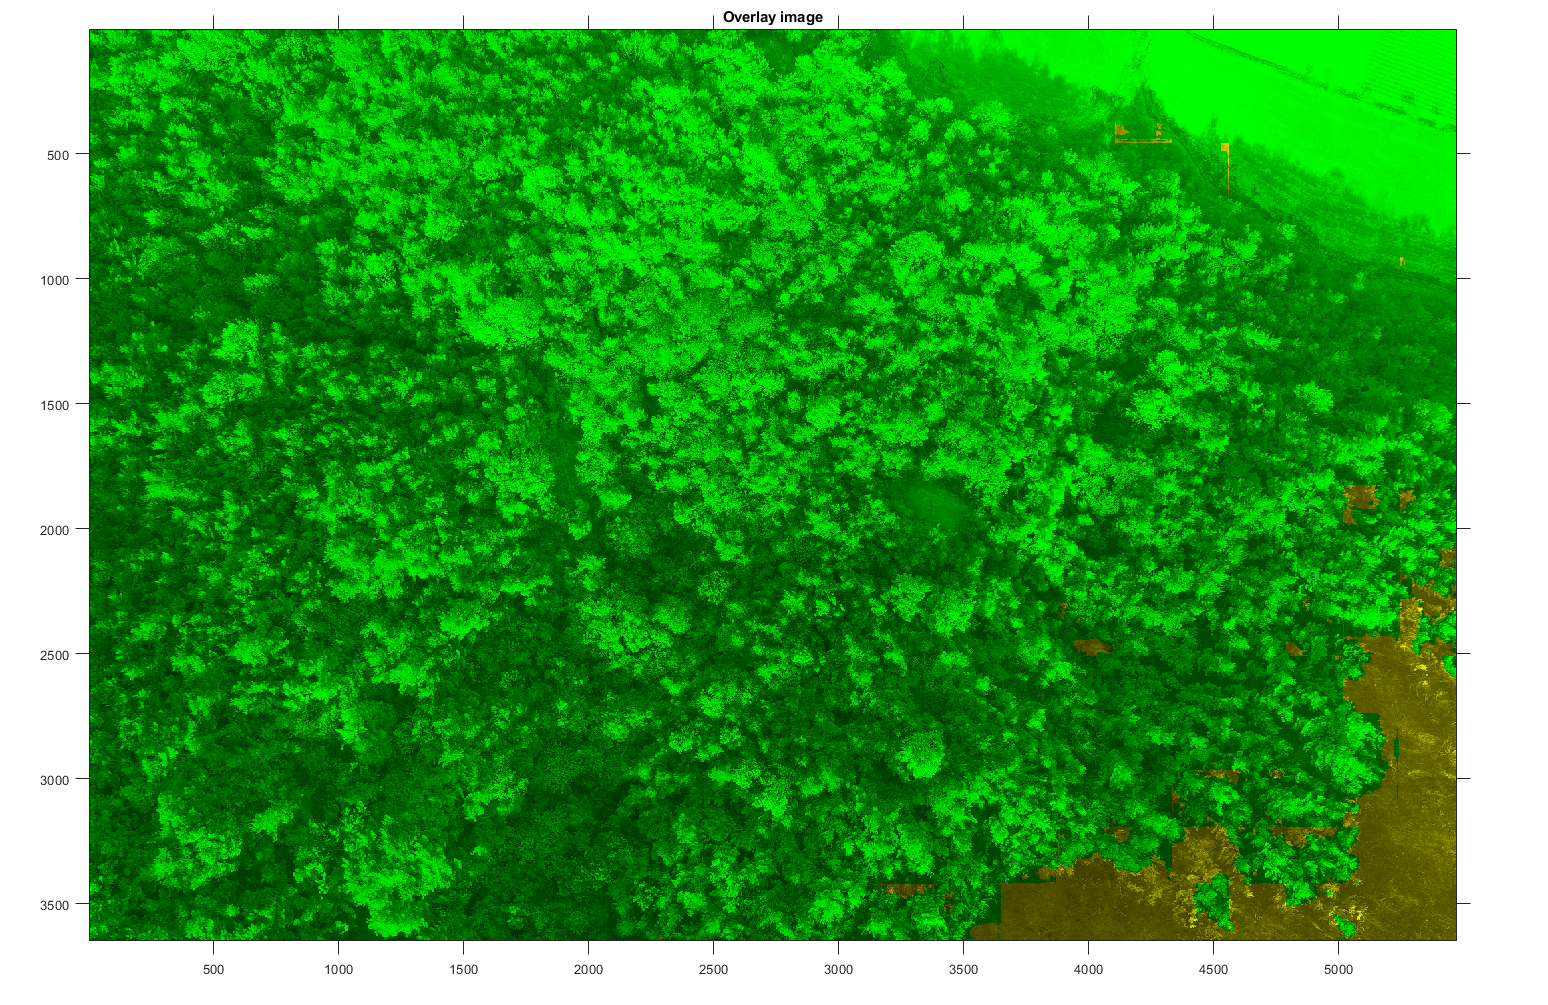

imshow(overlay_img)
axis on
title("Overlay image")